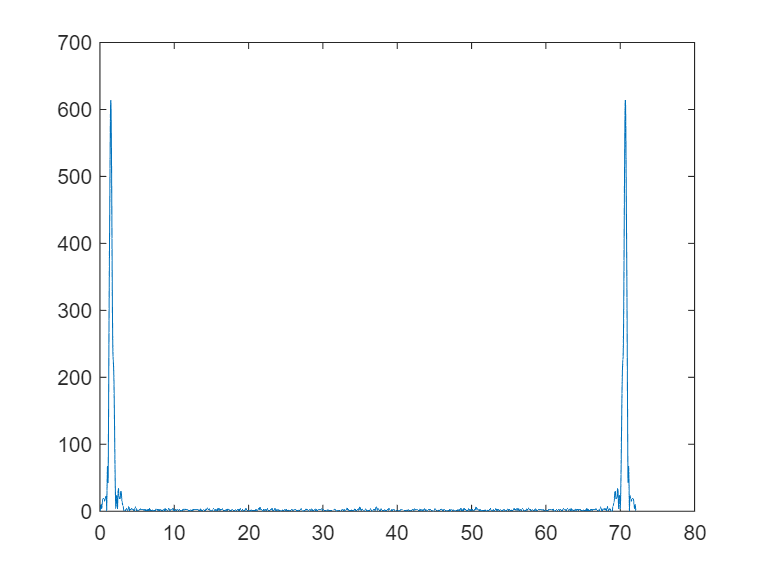

clear all; clc;
%-----------------------------------------------------------------------------------------------------
% 生成白光干涉信号
%显示光谱信息
spectrum = readtable("Isigma.xls","ReadVariableNames",false);
spectrum_frequency = (spectrum{:,1})';
spectrum_intensity = (spectrum{:,2})';
%disp("全部光谱信息");
plot(spectrum_frequency,spectrum_intensity)

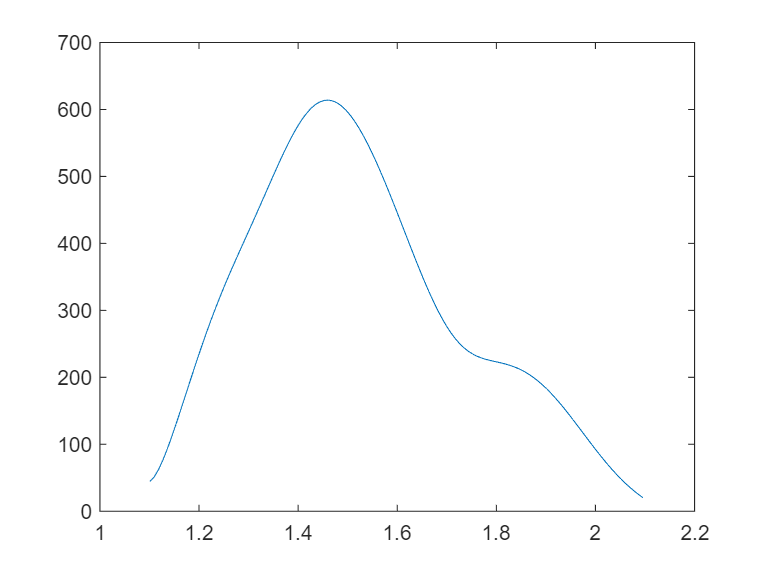

%找出探测器对应的光谱，这里假设是1.1-2.1
[~, indix_min] = min(abs(spectrum_frequency-1.1));
[~, indix_max] = min(abs(spectrum_frequency-2.1));
spectrum_frequency = spectrum_frequency(indix_min:indix_max);
spectrum_intensity = spectrum_intensity(indix_min:indix_max);
%disp("需要的光谱信息");
plot(spectrum_frequency,spectrum_intensity);

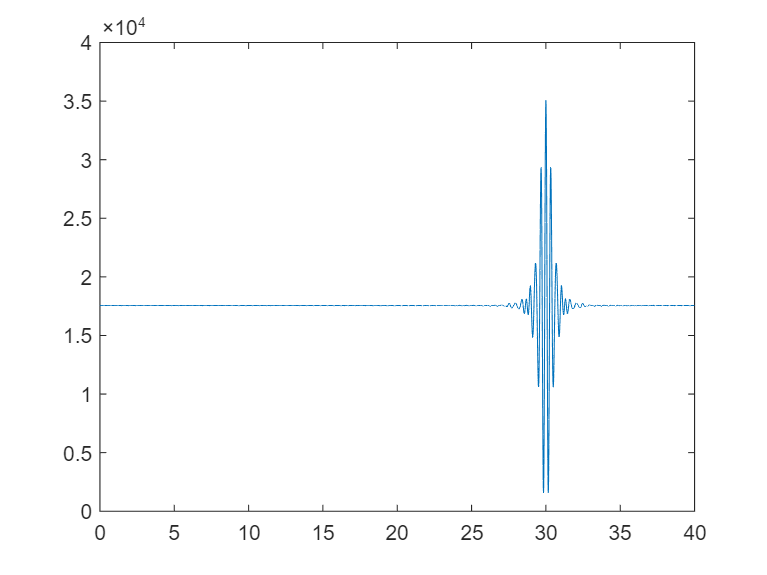

%生成白光干涉信号
z0 = 30;    %单位为微米
N = 4000;
z = 0:40/4000:(N-1)*(40/4000);
interference_signal = zeros(1,length(z));
for i = 1:length(z)
        interference_signal(i) = sum(spectrum_intensity./2+...
        spectrum_intensity./2.*cos(4*pi*(z(i)-z0).*spectrum_frequency));
end

%disp("生成的白光干涉信号");
plot(z,interference_signal);

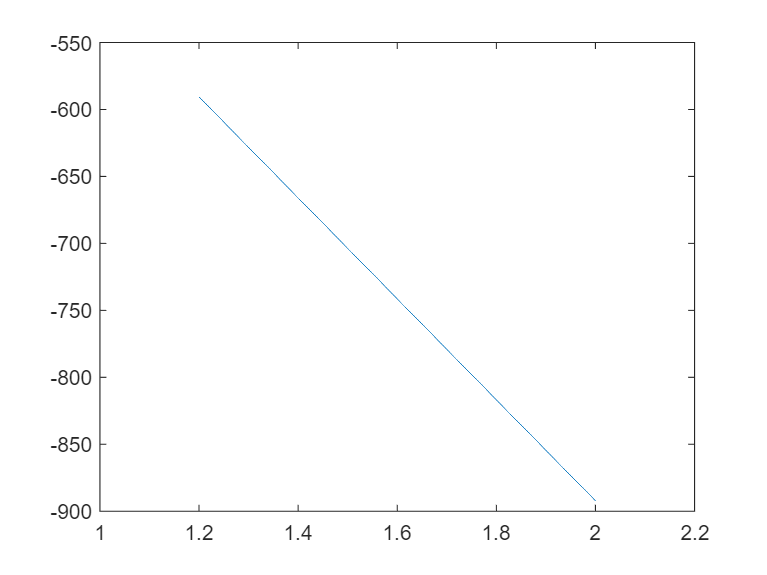

%-----------------------------------------------------------------------------------------------------
%对白光干涉信号进行傅里叶变换,由于直流项的存在，补零操作会导致频域震荡。
%滤除直流项
interference_signal = interference_signal-mean(interference_signal);
%fft补零
Nftt = 2^18;
f_interference_signal = fft(interference_signal,Nftt);
Fs = 1/(40/4000);
deltaSigma = Fs/(2*Nftt);
sigma = (0:Nftt/2)*deltaSigma;
abs_fis = abs(f_interference_signal(1:Nftt/2+1))*2/Nftt;
ang_fis = angle(f_interference_signal(1:Nftt/2+1));
ang_fis = unwrap(ang_fis);
%对应频率1.1-2.1
[~, indix_min] = min(abs(sigma-1.2));
[~, indix_max] = min(abs(sigma-2.0));
% ang_fis = unwrap(ang_fis(indix_min:indix_max));
%plot(sigma(indix_min:indix_max),abs_fis(indix_min:indix_max));
plot(sigma(indix_min:indix_max),ang_fis(indix_min:indix_max));

p1 = polyfit(sigma(indix_min:indix_max),ang_fis(indix_min:indix_max),1)

p1 =  -376.9914 -138.2296


%计算z0,误差
a01 = wrapToPi(p1(2))

a01 = 4.9135e-04

p1(1) = p1(1)-4*pi*z(1)

p1 =  -376.9914 -138.2296


calculate_z0 = p1(1)/(-4*pi)

calculate_z0 = 30.0000

diff_z0 = abs(calculate_z0-z0)

diff_z0 = 2.4597e-05

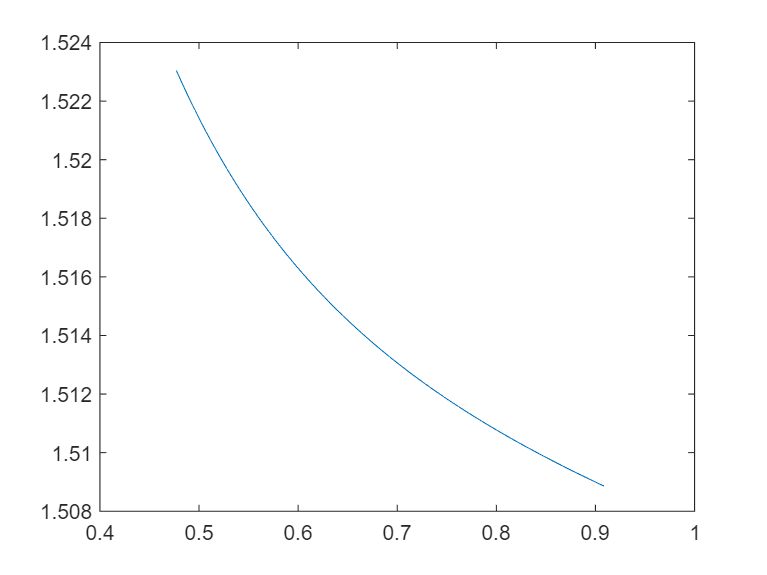


%-----------------------------------------------------------------------------------------------------
%加入色散
%色散公式
lambda = 1./spectrum_frequency;
index2 = (1.03961212*lambda.^2)./(lambda.^2-0.00600069867)+(1.01046945*lambda.^2)./(lambda.^2-103.560653)+...
        (0.231792344*lambda.^2)./(lambda.^2-0.0200179144)+1; 
index = sqrt(abs(index2));
%折射率曲线
%disp("折射率曲线");
plot(lambda,index);

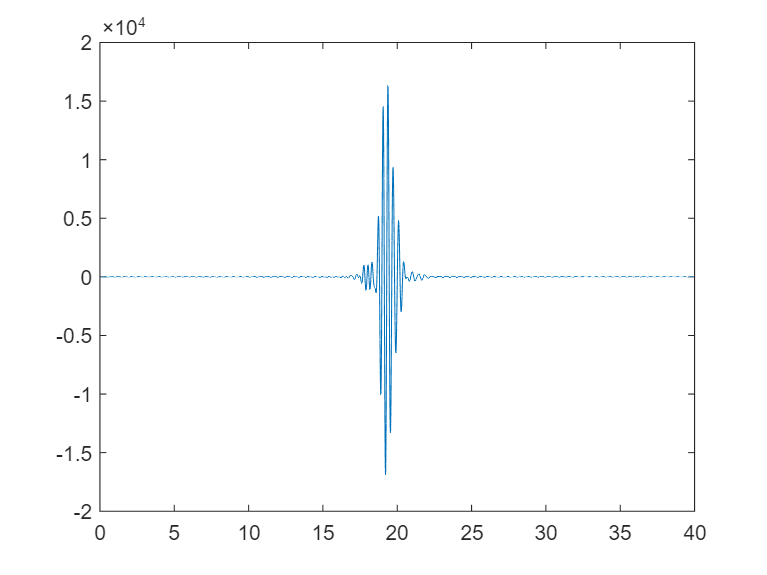

%色散
lEpsilon = 20; %单位为微米
N = 4000;
z = 0:40/4000:(N-1)*(40/4000);
interference_signal = zeros(1,length(z));
for i = 1:length(z)
    for n = 1:length(spectrum_frequency)
        interference_signal(i) = interference_signal(i)+spectrum_intensity(n)/2+...
        spectrum_intensity(n)/2*cos(4*pi*(z(i)-z0)*spectrum_frequency(n)+...
        4*pi*(index(n)-1)*spectrum_frequency(n)*lEpsilon);
    end
end
%disp("生成有色散的白光干涉信号");
% plot(z,interference_signal);
%-----------------------------------------------------------------------------------------------------
% 傅里叶变换
%对白光干涉信号进行傅里叶变换,由于直流项的存在，补零操作会导致频域震荡。
%滤除直流项
interference_signal = interference_signal-mean(interference_signal);
plot(z,interference_signal);

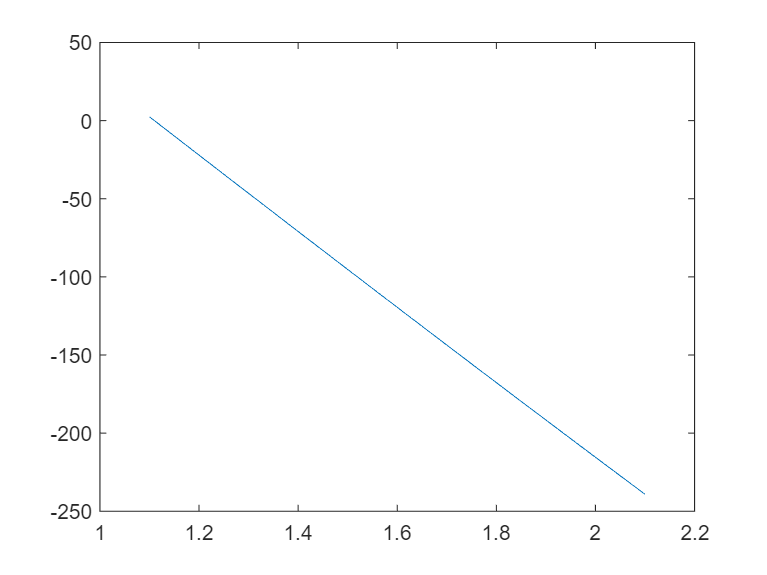

%fft补零
Nftt = 2^15;
f_interference_signal = fft(interference_signal,Nftt);
Fs = 1/(40/4000);
deltaSigma = Fs/(2*Nftt);
sigma = (0:Nftt/2)*deltaSigma;
abs_fis = abs(f_interference_signal(1:Nftt/2+1))*2/Nftt;
ang_fis = angle(f_interference_signal(1:Nftt/2+1));
ang_fis = unwrap(ang_fis);
%对应频率1.1-2.1
[~, indix_min] = min(abs(sigma-1.1));
[~, indix_max] = min(abs(sigma-2.1));
plot(sigma(indix_min:indix_max),ang_fis(indix_min:indix_max));

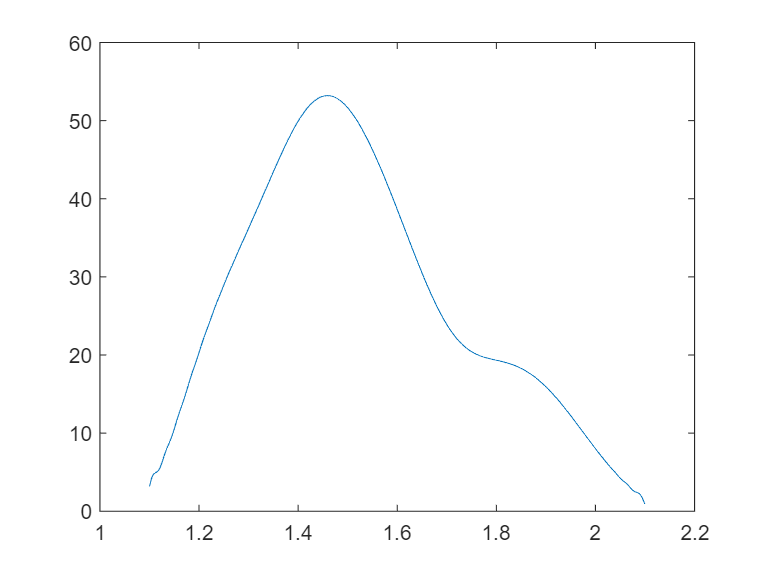

plot(sigma(indix_min:indix_max),abs_fis(indix_min:indix_max));

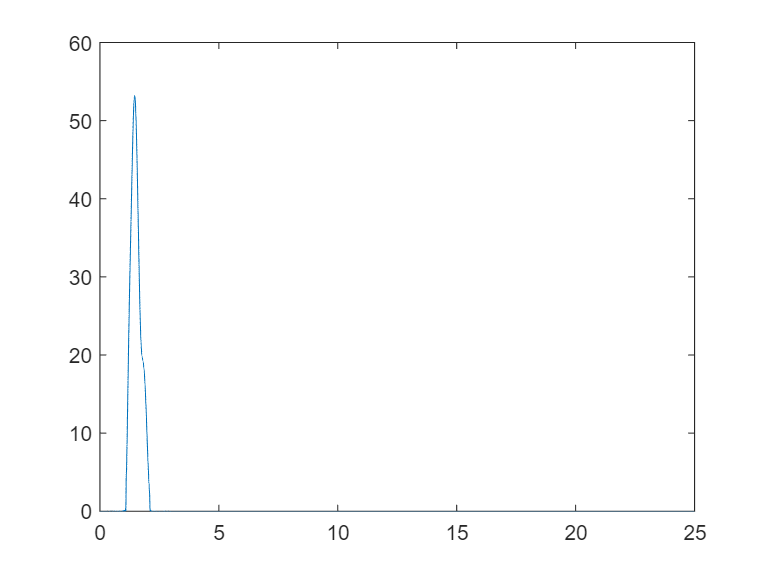

plot(sigma,abs_fis);

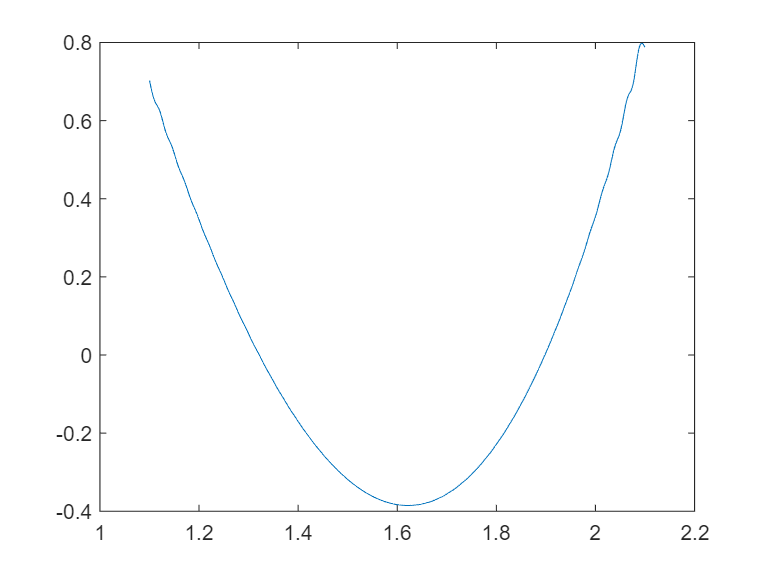

% plot(sigma(indix_min:indix_max),ang_fis(indix_min:indix_max));
p = polyfit(sigma(indix_min:indix_max),ang_fis(indix_min:indix_max),1);
% p2 = polyfit(sigma(indix_min:indix_max),ang_fis(indix_min:indix_max),2);
ang_fis_fit = polyval(p,sigma(indix_min:indix_max));
plot(sigma(indix_min:indix_max),ang_fis(indix_min:indix_max)-ang_fis_fit);

p(1) = p(1)-4*pi*z(1);
% a0 = p(2) - p2(3);
%-----------------------------------------------------------------------------------------------------
%傅里叶逆变换求z0
%正频域部分信号F(sigma)。
I_sigma = abs_fis;
P_sigma = polyval(p,sigma);
F_sigma = I_sigma.*exp(1i*P_sigma);
%计算加权平均波长
%lambdaA：加权平均波长
%powerTotal：总的波数振幅相加
%-----------------------------------
I_sigma1 = abs_fis(indix_min:indix_max);
sigma1 = sigma(indix_min:indix_max);
% powerTotal = 0;
% for n=1:1:length(I_sigma1)
%     powerTotal=powerTotal+I_sigma1(n);
% end
powerTotal = sum(I_sigma1);
% power = 0;
% for n=1:1:length(I_sigma1)
%     power = power+ I_sigma1(n)*sigma1(n);
% end
power = sum(I_sigma1.*sigma1);
lambdaA = powerTotal/power

lambdaA = 0.6566


%-----------------------------------
%逆傅里叶变换
Nifft = 2^20;
interference_signal1 = ifft(F_sigma,Nifft);
deltaSigma = (sigma(end)-sigma(1))/(length(sigma)-1);
deltaZ = 1/(2*Nifft*deltaSigma);
zData = (1:Nifft)*deltaZ;
intensity = abs(interference_signal1);
phase = angle(interference_signal1);
[~,index3]= max(intensity);
% plot(zData,intensity);xlim([zData(index3)-2 zData(index3)+2]);
% plot(zData,phase);xlim([zData(index3)-2 zData(index3)+2]);
za1 = zData(index3);
%-----------------------------------
[~,indexend] = min(abs(zData-(za1+0.5)));
[~,indexstart] = min(abs(zData-(za1-0.5)));
unwrapZend = zData(indexend);
unwrapZ_1 = zData(indexstart);
unwrapN1 = index3;
unwrapNe = find(zData==unwrapZend);
unwrapN_1 = find(zData==unwrapZ_1);
unwrapPha = zeros(1,length(zData));
unwrapPha(unwrapN1) = phase(index3);
for n = unwrapN1+1:unwrapNe
    diff = phase(n)-phase(n-1);
    if diff > pi/2
       unwrapPha(n) = unwrapPha(n-1)+diff-2*pi;
    elseif diff < -pi/2
       unwrapPha(n) = unwrapPha(n-1)+diff+2*pi;
    else
       unwrapPha(n) = unwrapPha(n-1)+diff;
    end
end
for n = unwrapN1:-1:unwrapN_1
    diff = phase(n)-phase(n-1);
    if diff > pi/2
       unwrapPha(n-1) = unwrapPha(n)-diff+2*pi;
    elseif diff < -pi/2
       unwrapPha(n-1) = unwrapPha(n)-diff-2*pi;
    else
       unwrapPha(n-1) = unwrapPha(n)-diff;
    end
end
% plot(zData(unwrapN_1:unwrapNe),unwrapPha(unwrapN_1:unwrapNe));
phase1=unwrapPha(unwrapN_1:unwrapNe);
zData1=zData(unwrapN_1:unwrapNe);
indexP = find(phase1>0);
indexN = find(phase1<0);
[phaseP,indexZP]= min(phase1(indexP));
[phaseN,indexZN]= max(phase1(indexN));
zData0P = zData1(indexP(indexZP));
zData0N = zData1(indexN(indexZN));
%-----------------------------------
%计算结果
a1 = p(1)+4*pi*z0;
a0 = wrapToPi(p(2));
za=z0-(a1/(4*pi));
zp=z0-((a1+a0*lambdaA)/(4*pi));
if za<0 && zp<0
zp1 = ((zData0N-zData0P)*phaseN)/(phaseP-phaseN)+zData0N-zData(end)
za1 = za1-zData(end)
zData = zData - zData(end);
else
zp1 = ((zData0N-zData0P)*phaseN)/(phaseP-phaseN)+zData0N
za1
end

zp1 = 19.3682

za1 = 19.2350

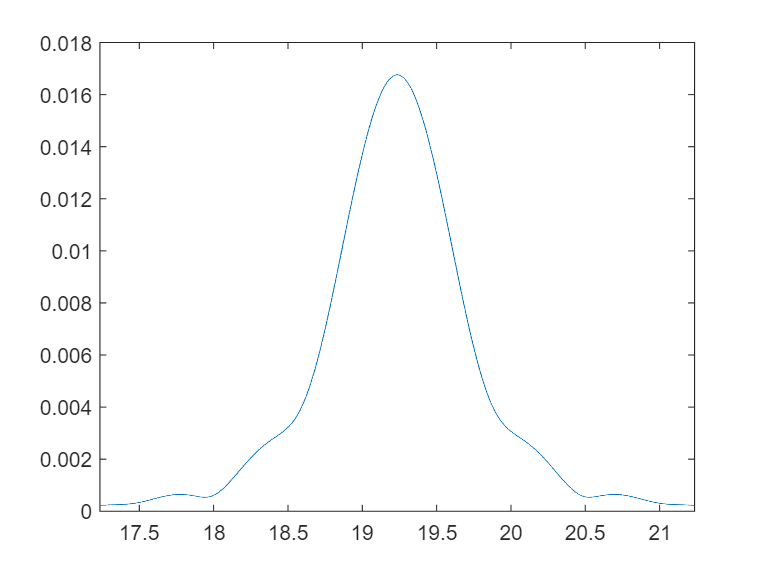

plot(zData,intensity);xlim([zData(index3)-2 zData(index3)+2]);

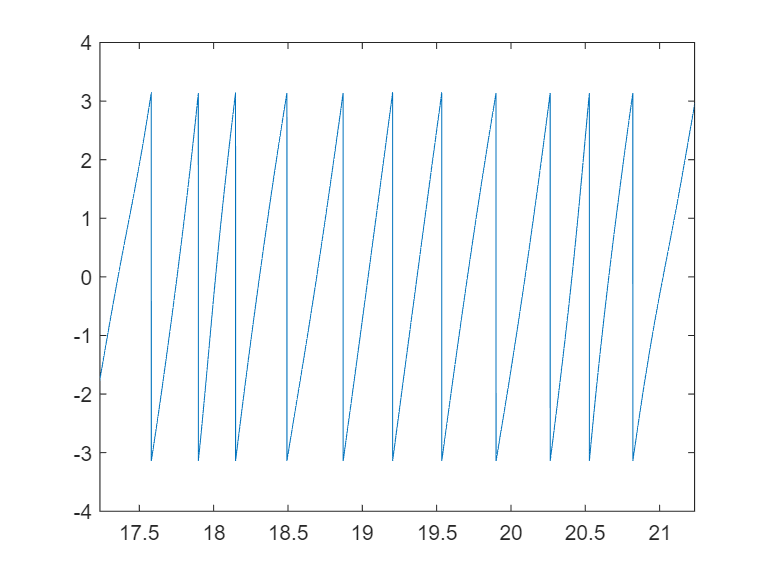

plot(zData,phase);xlim([zData(index3)-2 zData(index3)+2]);

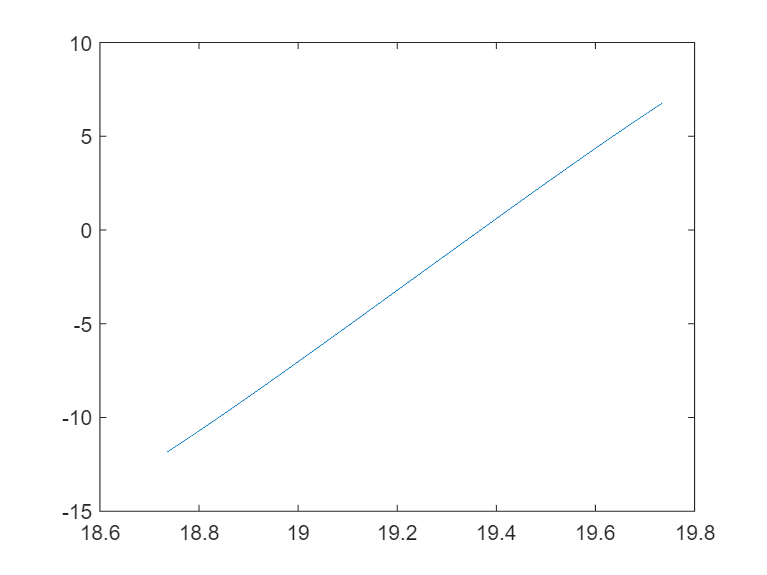

plot(zData(unwrapN_1:unwrapNe),unwrapPha(unwrapN_1:unwrapNe));

% zadiff = za1-za
% zpdiff = zp1-zp
z01 = za1+(a1/(4*pi))

z01 = 30.0004

z02 = zp1+((a1+a0*lambdaA)/(4*pi))

z02 = 30.0005

diff1 = z01-z0

diff1 = 3.7549e-04

diff2 = z02-z0

diff2 = 5.2206e-04